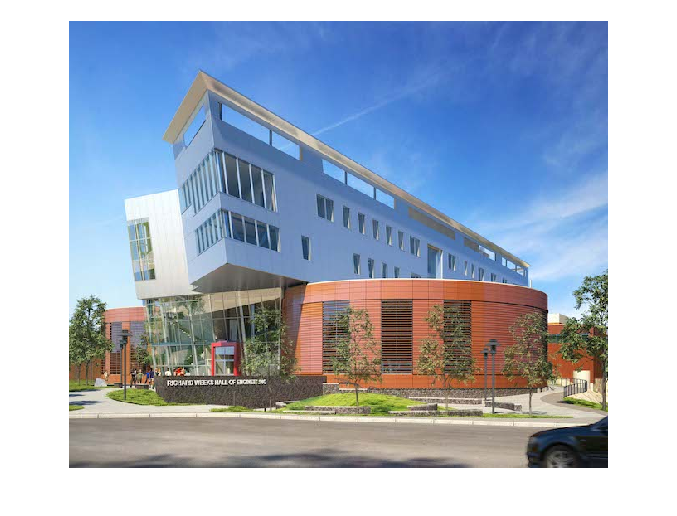

%2.1a

picture = imread("WeeksHallSmall.jpg");

imshow(picture);

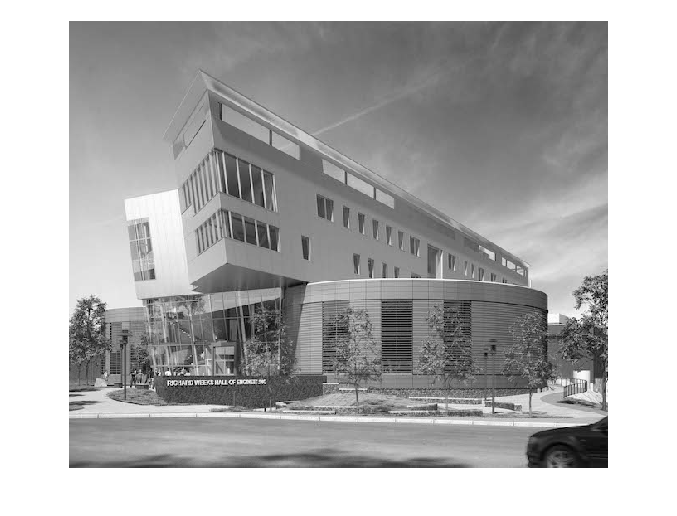


grayimage = rgb2gray(picture);

imshow(grayimage);


doubledgrayimage = double(grayimage);

[rows, cols] = size(doubledgrayimage);


average = mean(doubledgrayimage(:)); 



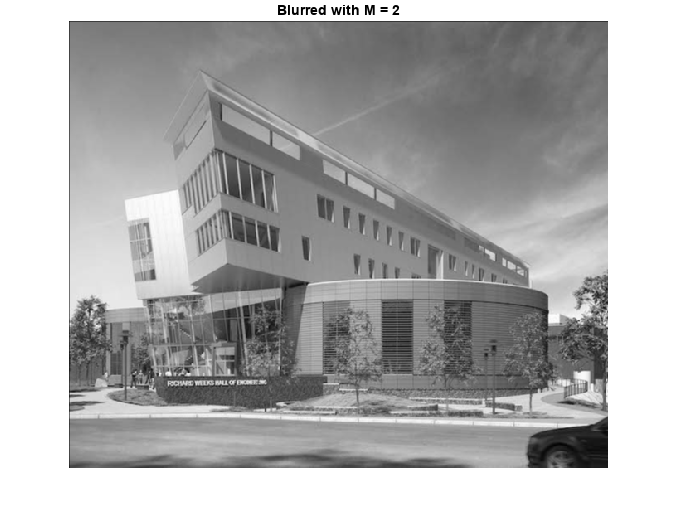

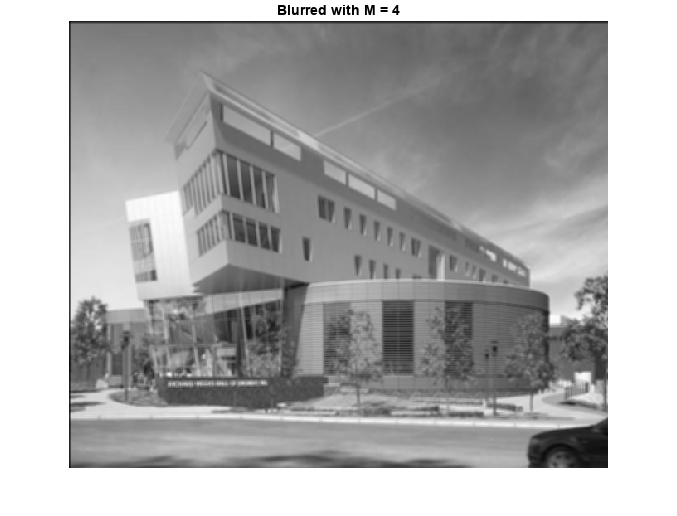

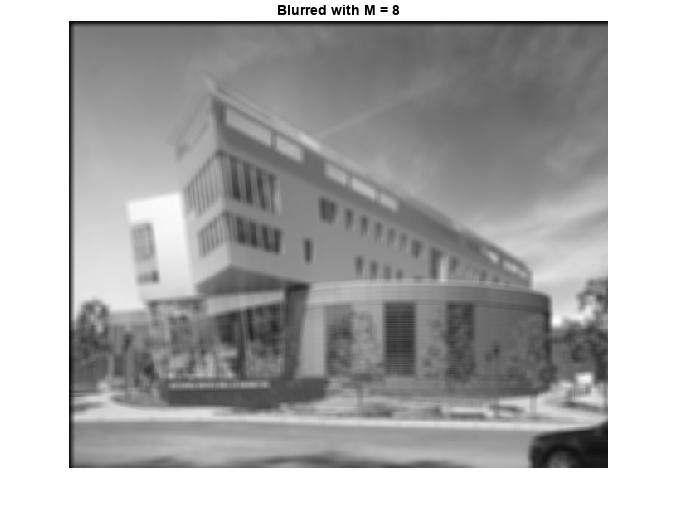

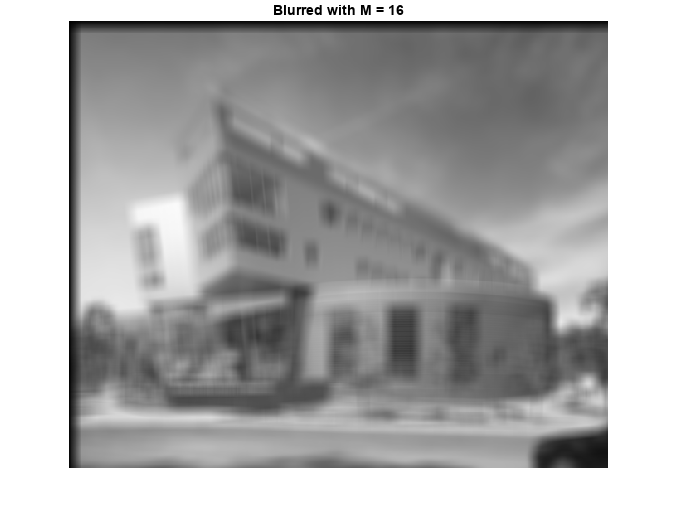

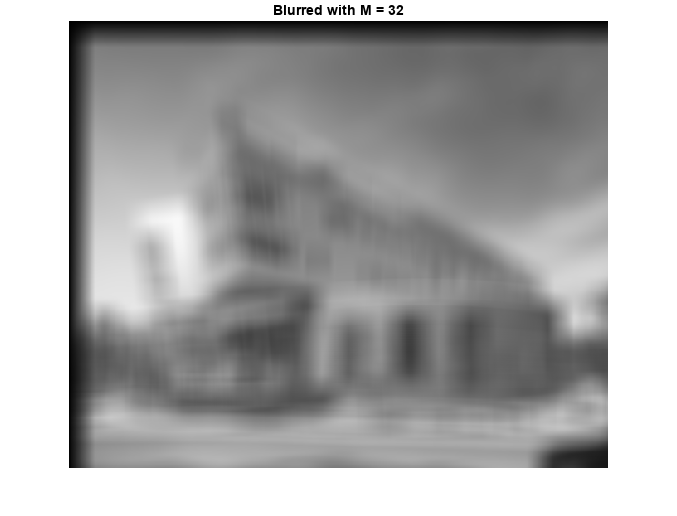


%2.1b

% Define M values
M_values = [2, 4, 8, 16, 32];

% Pre-allocate array to store blurred images for different M values
blurred_images = cell(size(M_values));

% Apply the filter for each M
for i = 1:length(M_values)
    M = M_values(i);

    % Create the averaging filter (box filter) kernel
    h = ones(1, M) / M;

    % Apply the filter to each row
    blurred_rows = filter(h, 1, grayimage, [], 2);

    % Apply the filter to each column
    blurred_image = filter(h, 1, blurred_rows, [], 1);

    % Store the blurred image
    blurred_images{i} = blurred_image;

    % Display the blurred image using imagesc or imshow
    figure;
    imshow(uint8(blurred_image));
    title(['Blurred with M = ', num2str(M)]);
end

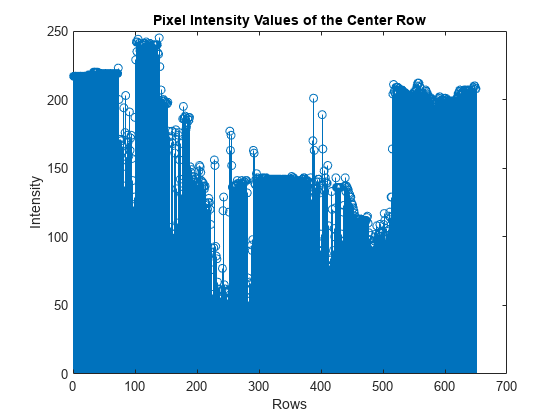

%2.1c

row_index = round(size(grayimage, 1) / 2);
selected_row = grayimage(row_index, :);
figure;
stem(selected_row);
title('Pixel Intensity Values of the Center Row');
xlabel('Rows');
ylabel('Intensity')

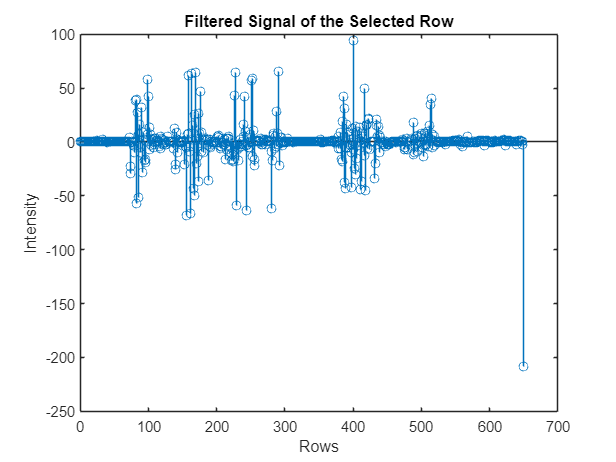



c = [1,-1];
filtered_row = conv(selected_row, c, 'same');
figure;
stem(filtered_row);
title('Filtered Signal of the Selected Row');
xlabel('Rows');
ylabel('Intensity')

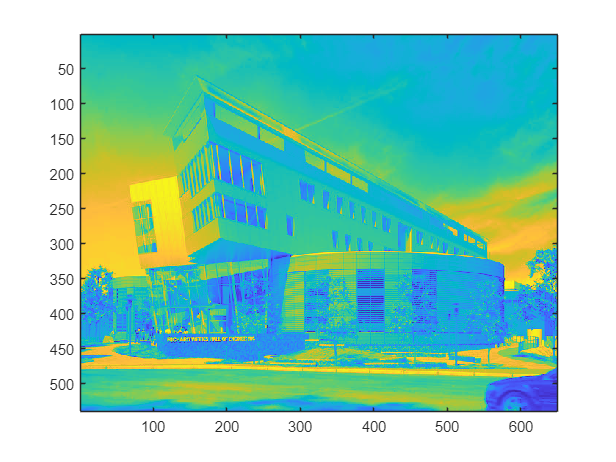


c = [1, -1];

% Initialize matrices to store the convolution results
% filtered_rows = zeros(size(grayimage));
filtered_cols = zeros(size(grayimage));

% Convolve the filter with each row
for i = 1:size(grayimage, 1)
    filtered_rows(i, :) = conv(grayimage(i, :), c, 'same');
end

% Convolve the filter with each column
for j = 1:size(grayimage, 2)
    filtered_cols(:, j) = grayimage(:, j);
end

threshold_value = 9;  % Adjust this value based on your specific image

% Apply thresholding to the row-filtered image
binary_edge_image = abs(filtered_rows) > threshold_value;


imagesc(grayimage)

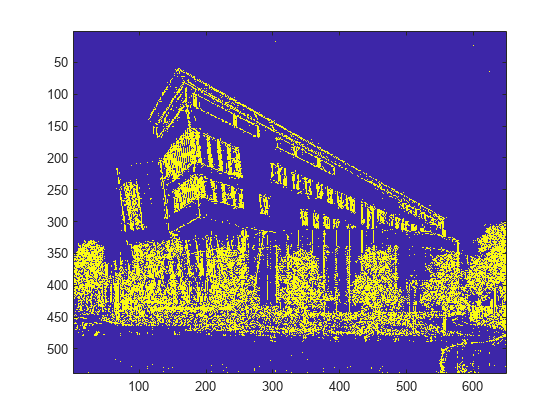

imagesc(binary_edge_image);



%Testing stuff
c = [1, -1];

% Initialize matrices to store the convolution results
filtered_rows = zeros(size(grayimage));
filtered_cols = zeros(size(grayimage));

% Convolve the filter with each row
for i = 1:size(grayimage, 1)
    filtered_rows(i, :) = conv(grayimage(i, :), c, 'same');
end

% Convolve the filter with each column
for j = 1:size(grayimage, 2)
    filtered_cols(:, j) = grayimage(:, j);
end




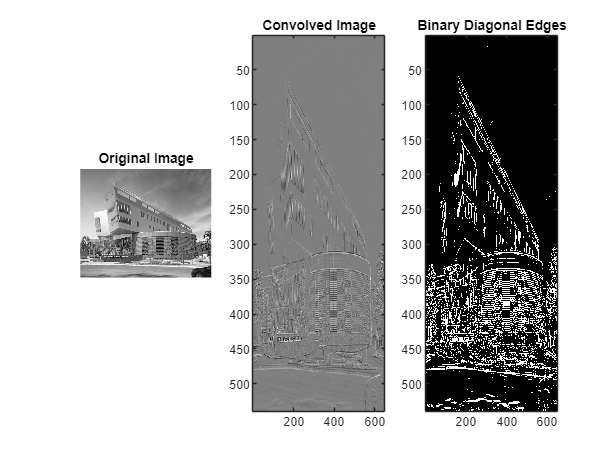



%2.1d


% Define the filter Dur
Dur = [0 0 -1; 0 1 0; 0 0 0];

% Convolve Dur with the image using conv2
convolved_image = conv2(double(grayimage), Dur, 'same');

% Threshold the output to reveal diagonal edges
threshold_value = 10; % Adjust this value based on your specific image and requirements
binary_diagonal_edges = convolved_image > threshold_value;

% Display the original image, convolved image, and binary diagonal edges
figure;
subplot(1, 3, 1);
imshow(grayimage);
title('Original Image');

subplot(1, 3, 2);
imagesc(convolved_image);
title('Convolved Image');

subplot(1, 3, 3);
imagesc(binary_diagonal_edges);
title('Binary Diagonal Edges');

colormap(gray); % Use a grayscale colormap for better visualization

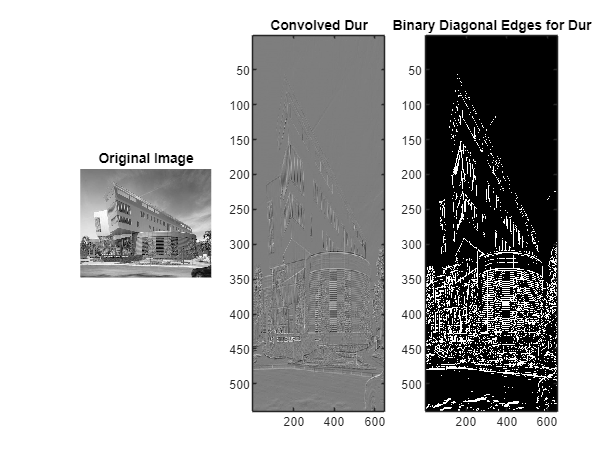

%2.1d

Dul = [-1 0 0; 0 1 0; 0 0 0];


threshold_value = 10;
convolvedDur = conv2(double(grayimage), Dul, 'same');

Dur_diagonal_edges = convolvedDur > threshold_value;

% Display the original image, convolved image, and binary diagonal edges
figure;
subplot(1, 3, 1);
imshow(grayimage);
title('Original Image');

subplot(1, 3, 2);
imagesc(convolvedDur);
title('Convolved Dur');

subplot(1, 3, 3);
imagesc(Dur_diagonal_edges);
title('Binary Diagonal Edges for Dur');

colormap(gray); % Use a grayscale colormap for better visualization

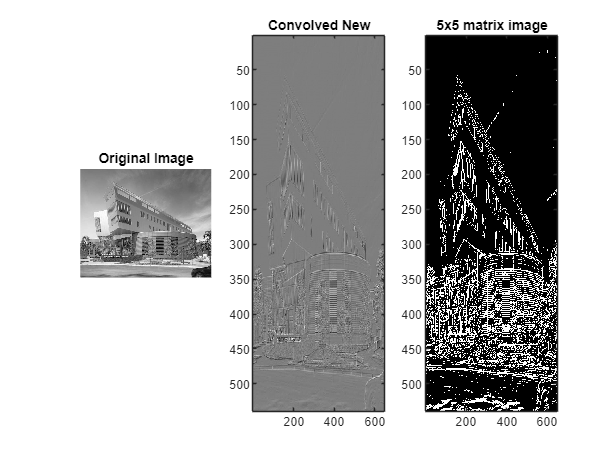

%2.1e

Dnew = [0, 0, 0, 0, 0;
     0, 0, 0, 0, 0;
     0, -1, 0, 0, 0;
     0, 0, 1, 0, 0;
     0, 0, 0, 0, 0];

threshold_value = 6;
convolvedNew = conv2(double(grayimage), Dnew, 'same');

Dnew_edges = convolvedNew > threshold_value;

% Display the original image, convolved image, and binary diagonal edges
figure;
subplot(1, 3, 1);
imshow(grayimage);
title('Original Image');

subplot(1, 3, 2);
imagesc(convolvedNew);
title('Convolved New');

subplot(1, 3, 3);
imagesc(Dnew_edges);
title('5x5 matrix image');

colormap(gray); % Use a grayscale colormap for better visualization

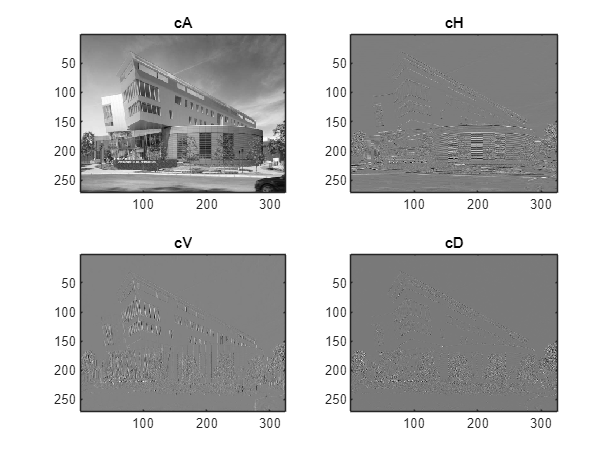

%2.2a

%dwt stuff
newgrayimage = rgb2gray(picture);

[cA, cH, cV, cD] = dwt2(newgrayimage, 'haar');

figure;

subplot(2, 2, 1);
imagesc(cA);
colormap gray;
title('cA');

subplot(2, 2, 2);
imagesc(cH);
colormap gray;
title('cH');

subplot(2, 2, 3);
imagesc(cV);
colormap gray;
title('cV');

subplot(2, 2, 4);
imagesc(cD);
colormap gray;
title('cD');

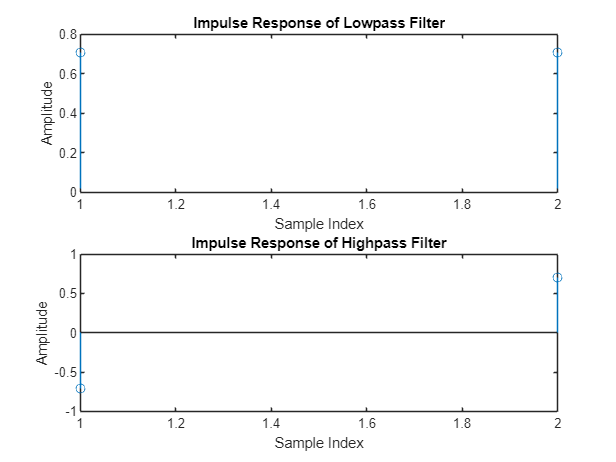


% Obtain filter coefficients using wfilters
[lowpass, highpass] = wfilters('haar');

% Display impulse response of the lowpass filter
figure;
subplot(2, 1, 1);
stem(lowpass);
title('Impulse Response of Lowpass Filter');
xlabel('Sample Index');
ylabel('Amplitude');

% Display impulse response of the highpass filter
subplot(2, 1, 2);
stem(highpass);
title('Impulse Response of Highpass Filter');
xlabel('Sample Index');
ylabel('Amplitude');


% Calculate energy in the impulse response
energy_lowpass = sum(abs(lowpass).^2);
energy_highpass = sum(abs(highpass).^2);

fprintf('Energy in Lowpass Filter: %f\n', energy_lowpass);

Energy in Lowpass Filter: 1.000000


fprintf('Energy in Highpass Filter: %f\n', energy_highpass);

Energy in Highpass Filter: 1.000000



% Explanation of energy choice
disp('Choosing energy in the impulse response makes sense because it reflects the overall power or strength of the filter. A higher energy value indicates a more powerful filter, capable of capturing and preserving more information. In the context of signal processing, filters with higher energy in their impulse response are often preferred as they can better represent and retain important features of the signal.');

Choosing energy in the impulse response makes sense because it reflects the overall power or strength of the filter. A higher energy value indicates a more powerful filter, capable of capturing and preserving more information. In the context of signal processing, filters with higher energy in their impulse response are often preferred as they can better represent and retain important features of the signal.


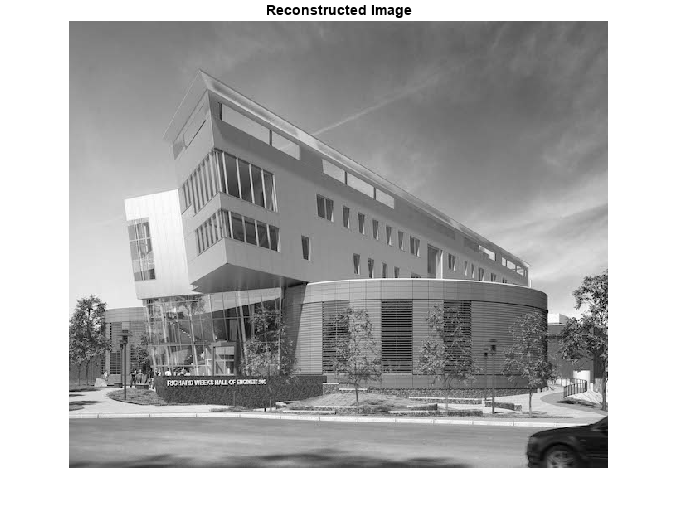

%2.2b 

% Assuming cA, cH, cV, cD are obtained from the wavelet transform
reconstructed_image = idwt2(cA, cH, cV, cD, 'haar', size(newgrayimage));

% Display the reconstructed image
figure;
imshow(uint8(reconstructed_image));
title('Reconstructed Image');

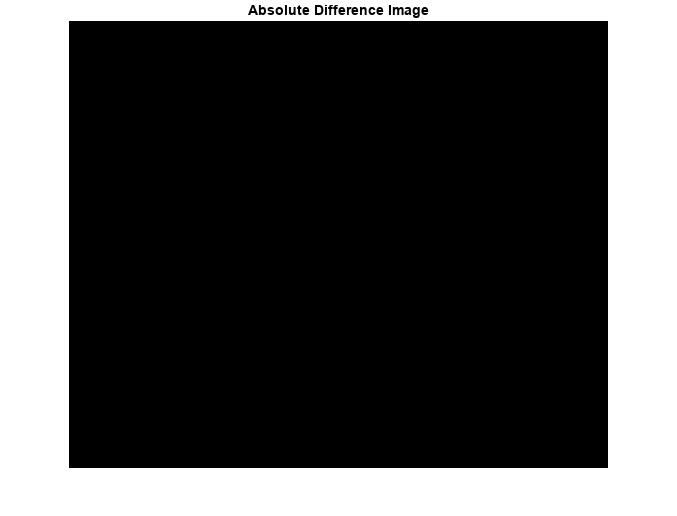


% Calculate the difference between the reconstructed image and the original
difference_image = double(newgrayimage) - double(reconstructed_image);

% Display the difference image
figure;
imshow(uint8(abs(difference_image)));
title('Absolute Difference Image');


% Calculate the total squared error per pixel
squared_error_per_pixel = sum(difference_image(:).^2) / numel(newgrayimage);
fprintf('Total Squared Error per Pixel: %.2f\n', squared_error_per_pixel);

Total Squared Error per Pixel: 0.00



% Calculate the maximum absolute difference
max_absolute_difference = max(abs(difference_image(:)));
fprintf('Maximum Absolute Difference: %.2f\n', max_absolute_difference);

Maximum Absolute Difference: 0.00



% Find the entry in D with the maximum value
[max_value, max_index] = max(difference_image(:));
[row, col] = ind2sub(size(difference_image), max_index);
fprintf('Coordinates of Maximum Value: Row %d, Column %d\n', row, col);

Coordinates of Maximum Value: Row 438, Column 124


fprintf('Maximum Value: %.2f\n', max_value);

Maximum Value: 0.00


%2.2c

% Sizes of the matrices
original_size = numel(newgrayimage);
approximation_size = numel(cA);

% Compression ratio
compression_ratio = original_size / approximation_size;

fprintf('Original Size: %d\n', original_size);

Original Size: 350350


fprintf('Approximation Size: %d\n', approximation_size);

Approximation Size: 87750


fprintf('Compression Ratio: %.2f\n', compression_ratio);

Compression Ratio: 3.99


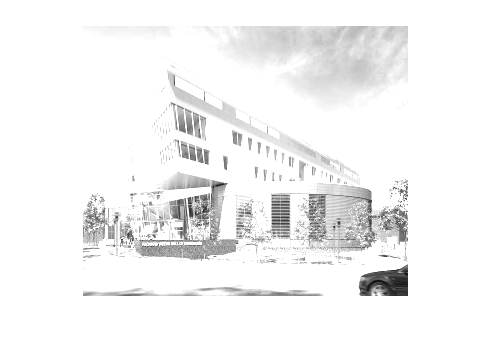

%2.2d

lowdetail = dwt2(newgrayimage, 'haar'); %Zeroed out edges, "low detailed image
imshow(uint8(lowdetail));